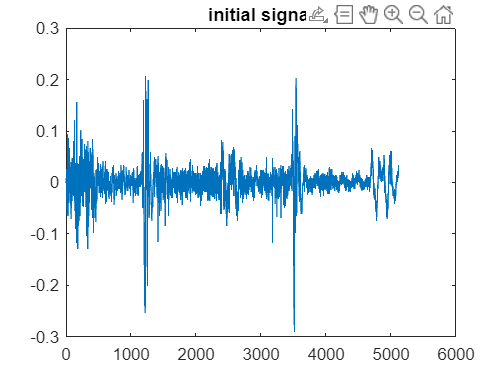

clear
clc

load('X_in_0.txt')

plot(X_in_0)
title('initial signal')


hilb=hilbert(X_in_0)

hilb =   -0.0000 + 0.0254i
   0.0010 + 0.0111i
   0.0092 + 0.0123i
   0.0044 + 0.0309i
  -0.0332 + 0.0173i
  -0.0085 - 0.0262i
   0.0176 + 0.0041i
  -0.0081 + 0.0020i
   0.0129 - 0.0150i
   0.0255 + 0.0073i


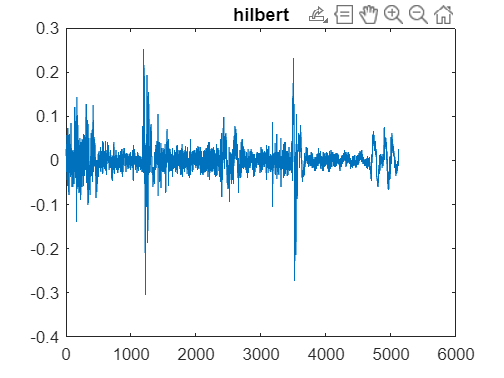


figure(1)
plot(imag(hilb))
title('hilbert')

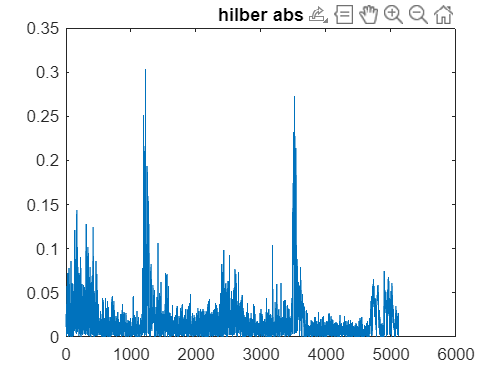

plot(abs(imag(hilb)))
title('hilber abs')

firedecim = dsp.FIRDecimator(20)

firedecim =   dsp.FIRDecimator with properties:

   Main
    DecimationFactor: 20
     NumeratorSource: 'Property'
           Numerator: [0 -6.3125e-07 -1.4075e-06 -2.3192e-06 -3.3488e-06 -4.4710e-06 -5.6525e-06 -6.8522e-06 -8.0222e-06 -9.1088e-06 -1.0054e-05 -1.0797e-05 -1.1276e-05 -1.1432e-05 -1.1209e-05 -1.0559e-05 -9.4422e-06 -7.8323e-06 … ] (1×480 double)
           Structure: 'Direct form'

  Show all properties


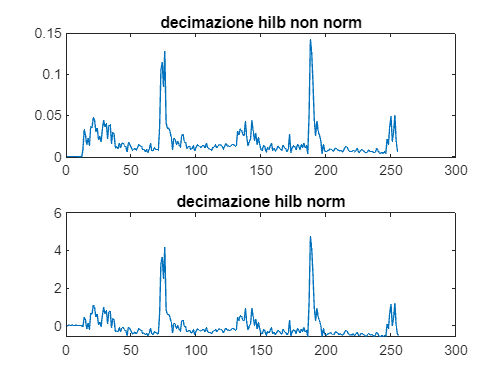


figure(2)
subplot(2,1,1)
x_out = firedecim(abs(imag(hilb)));
plot(x_out)
title('decimazione hilb non norm')

subplot(2,1,2)
x_out_n = firedecim(normalize(abs(imag(hilb))));
plot(x_out_n)
title('decimazione hilb norm')

figure(3)
subplot(2,1,1)
x_out_norm = normalize(x_out);
mean(x_out_norm)

ans = 6.9389e-18

std(x_out_norm)

ans = 1.0000

plot(x_out_norm)
title('normalizzazione output hilb non norm')

subplot(2,1,2)
x_out_norm = normalize(x_out_n);
mean(x_out_norm)

ans = -1.7347e-17

std(x_out_norm)

ans = 1

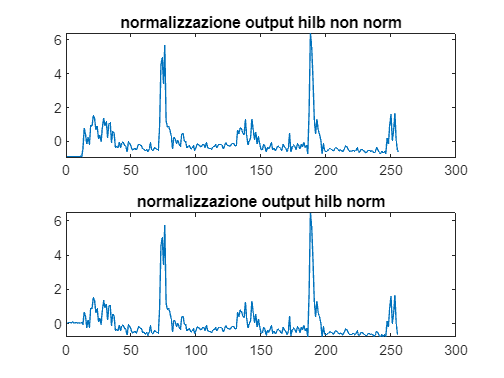

plot(x_out_norm)
title('normalizzazione output hilb norm')